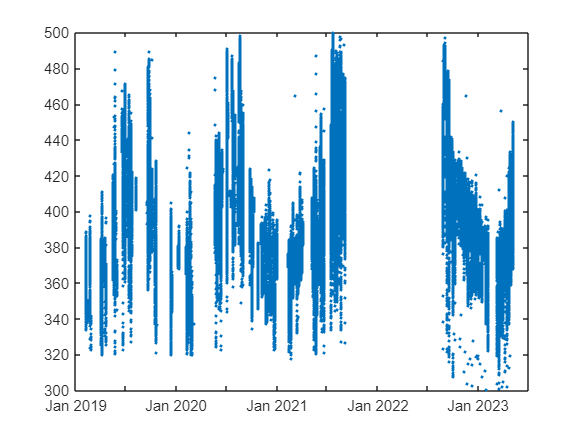

As = vertcat(A1, A2, A3);
plot(As.Date, As.fCO2sw, ".")

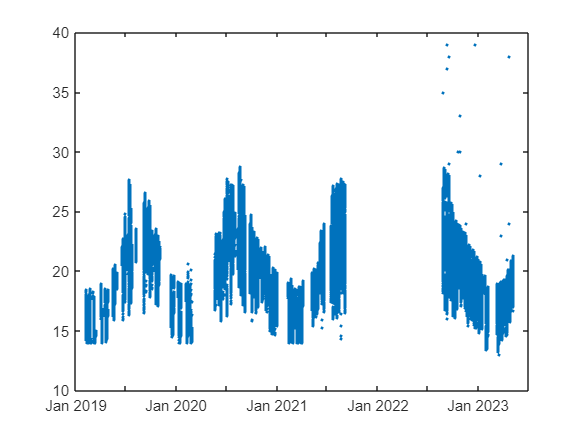

plot(As.Date, As.IntakeTemp, ".")

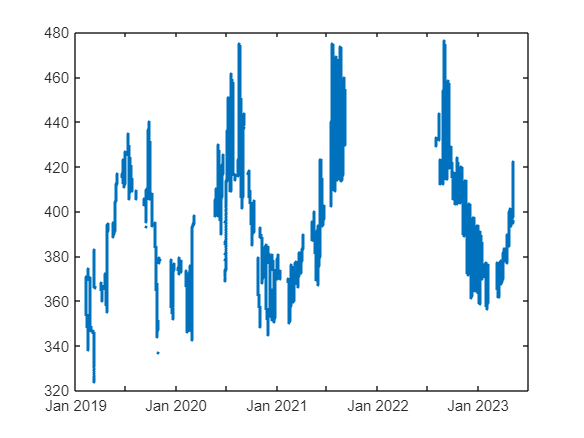

plot(As1.Date, As1.fCO2sw, ".")

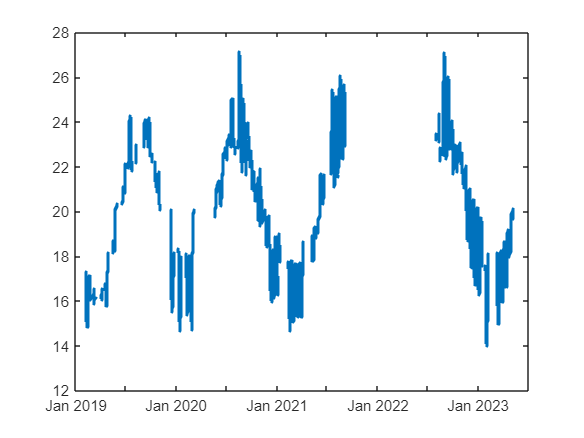

plot(As1.Date, As1.IntakeTemp, ".")

As1.latitude(As1.latitude > 90)= NaN;

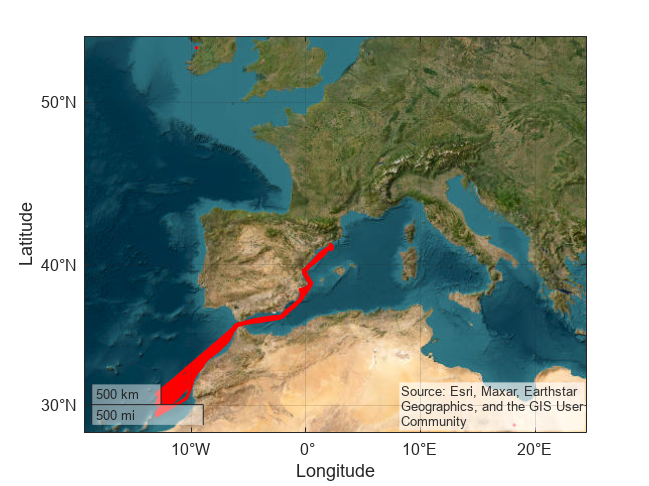

geoplot(As1.latitude, As1.longitude, "r.")
geobasemap satellite

As1.YearFraction = 2019+(As1.JulianDate-43466)./365.25;


% m1a = As1(As1.longitude < -11.62 & As1.longitude > -11.72 & As1.latitude > 31, :);
% m1b = As1(As1.longitude < -11.62 & As1.longitude > -11.72 & As1.latitude < 31, :);
m2 = As1(As1.longitude < -10.01 & As1.longitude > -10.11 & As1.latitude > 32.1, :);
m3 = As1(As1.longitude < -8.39 & As1.longitude > -8.49 & As1.latitude < 34, :);
m4 = As1(As1.longitude < -6.89 & As1.longitude > -6.99 & As1.latitude > 34.7, :);
m5 = As1(As1.longitude < -4.95 & As1.longitude > -5.05, :);
m6 = As1(As1.longitude < -3.75 & As1.longitude > -3.85, :);
m7 = As1(As1.longitude < -1.71 & As1.longitude > -1.81, :);
m8 = As1(As1.longitude < -0.04 & As1.longitude > -0.14 & As1.latitude < 38.3, :);
m9 = As1(As1.longitude < 0.80 & As1.longitude > 0.70, :);

Ac.YearFraction = 2019+(Ac.JulianDate-43466)./365.25;

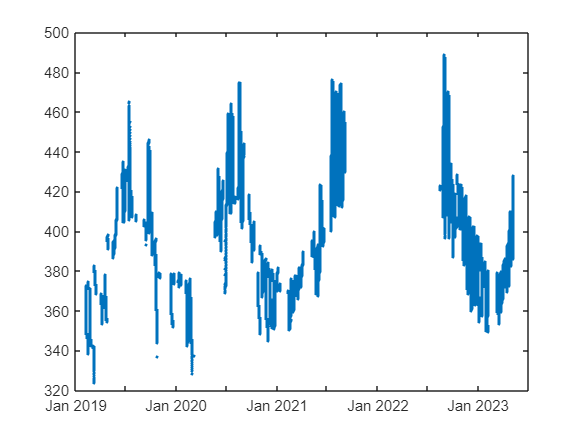

plot(Ac.Date, Ac.fCO2sw, ".")

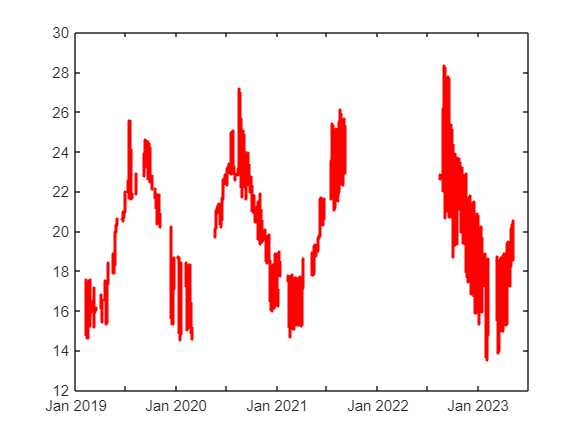

plot(Ac.Date, Ac.IntakeTemp, ".r")

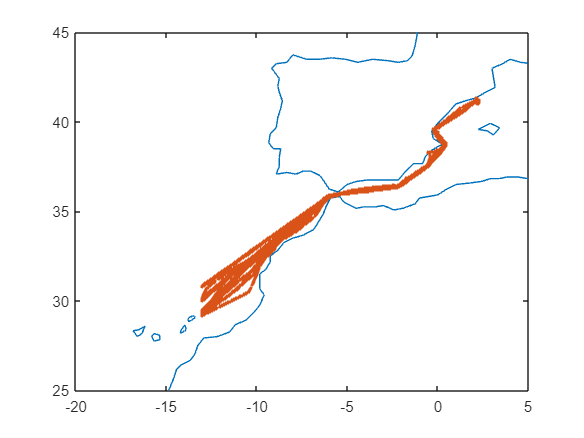

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(Ac.longitude, Ac.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

Ac.latitude(Ac.latitude > 90)= NaN;

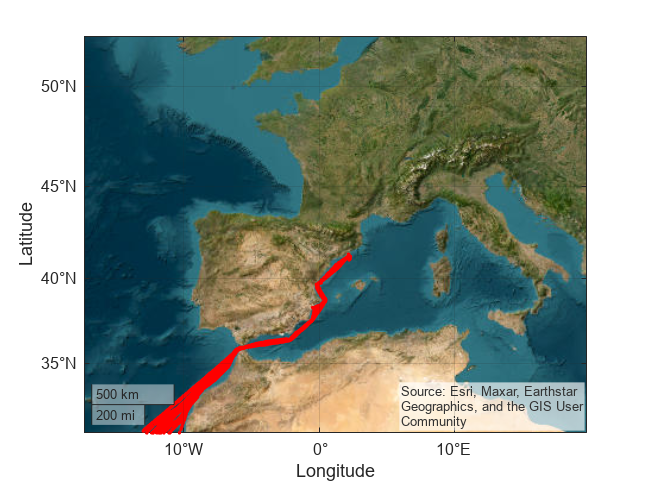

% geoplot(Ac.latitude, Ac.longitude, "r.")
% geobasemap satellite

Ac.YearFraction = 2019+(Ac.JulianDate-43466)./365.25;


m1 = Ac(Ac.longitude < -11.62 & Ac.longitude > -11.72 & Ac.latitude < 31.5 & Ac.latitude > 30.6, :);
m2 = Ac(Ac.longitude < -10.01 & Ac.longitude > -10.11 & Ac.latitude > 32.1, :);
m3 = Ac(Ac.longitude < -8.39 & Ac.longitude > -8.49 & Ac.latitude < 34, :);
m4 = Ac(Ac.longitude < -6.89 & Ac.longitude > -6.99 & Ac.latitude > 34.7, :);
m5 = Ac(Ac.longitude < -4.95 & Ac.longitude > -5.05, :);
m6 = Ac(Ac.longitude < -3.75 & Ac.longitude > -3.85, :);
m7 = Ac(Ac.longitude < -1.71 & Ac.longitude > -1.81, :);
m8 = Ac(Ac.longitude < -0.04 & Ac.longitude > -0.14 & Ac.latitude < 38.3, :);
m9 = Ac(Ac.longitude < 0.80 & Ac.longitude > 0.70, :);

m4.fCO2sw(m4.fCO2sw < 340) = NaN;
m1.fCO2sw(m1.fCO2sw < 340) = NaN;
m8.fCO2sw(m8.fCO2sw < 340) = NaN;

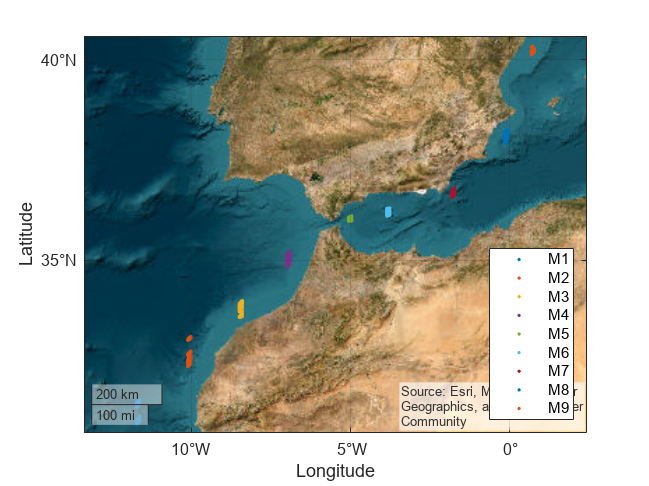

% plot(coastlon, coastlat)
% hold on
geoplot(m1.latitude, m1.longitude, ".")
hold on
geoplot(m2.latitude, m2.longitude, ".")
hold on
geoplot(m3.latitude, m3.longitude, ".")
hold on
geoplot(m4.latitude, m4.longitude, ".")
hold on
geoplot(m5.latitude, m5.longitude, ".")
hold on
geoplot(m6.latitude, m6.longitude, ".")
hold on
geoplot(m7.latitude, m7.longitude, ".")
hold on
geoplot(m8.latitude, m8.longitude, ".")
hold on
geoplot(m9.latitude, m9.longitude, ".")
hold off
% xlim([-20 5])
% ylim([25 45])
legend(["M1", "M2", "M3", "M4", "M5", "M6", "M7", "M8", "M9"], "Location","southeast")

geobasemap satellite

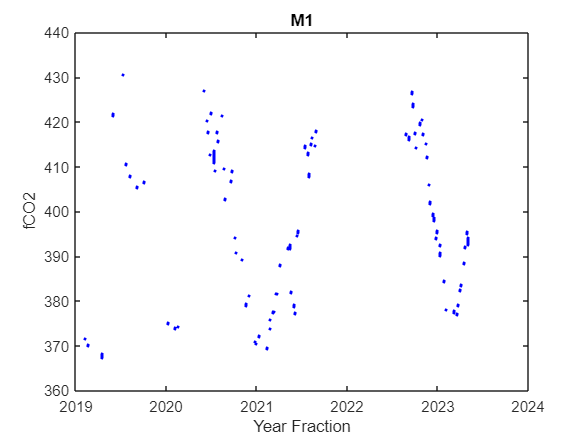

plot(m1.YearFraction, m1.fCO2sw, "b.")
title("M1")
ylabel("fCO2")
xlabel("Year Fraction")

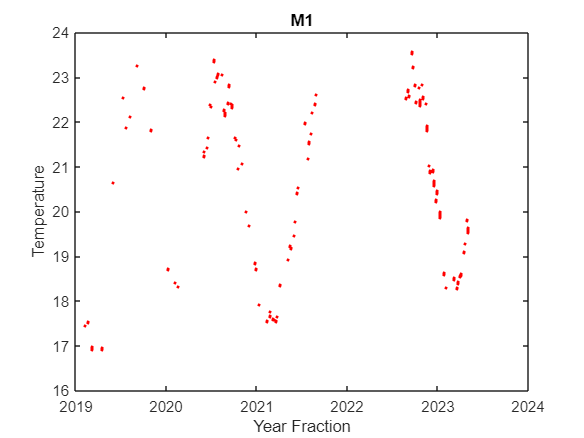


plot(m1.YearFraction, m1.IntakeTemp, ".r")
title("M1")
ylabel("Temperature")
xlabel("Year Fraction")

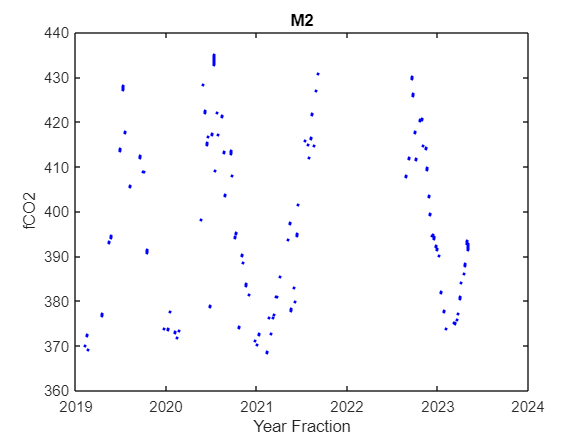



plot(m2.YearFraction, m2.fCO2sw, "b.")
title("M2")
ylabel("fCO2")
xlabel("Year Fraction")

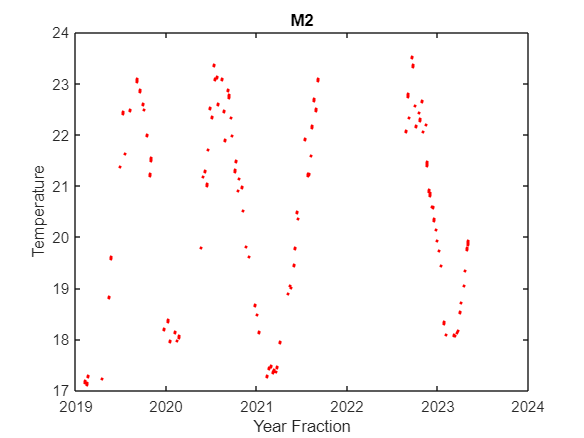


plot(m2.YearFraction, m2.IntakeTemp, ".r")
title("M2")
ylabel("Temperature")
xlabel("Year Fraction")

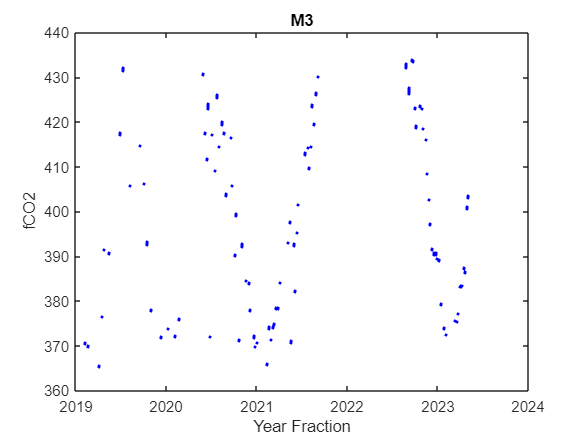



plot(m3.YearFraction, m3.fCO2sw, "b.")
title("M3")
ylabel("fCO2")
xlabel("Year Fraction")

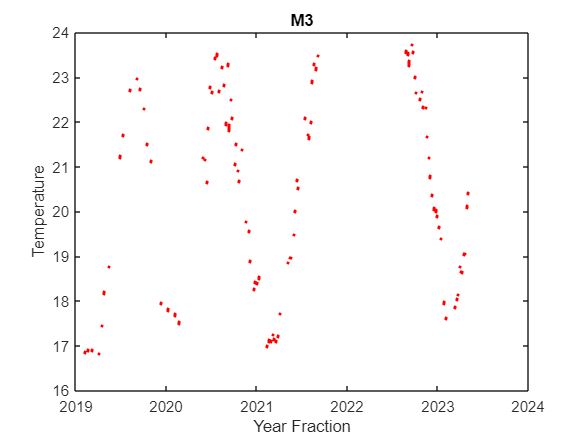


plot(m3.YearFraction, m3.IntakeTemp, ".r")
title("M3")
ylabel("Temperature")
xlabel("Year Fraction")

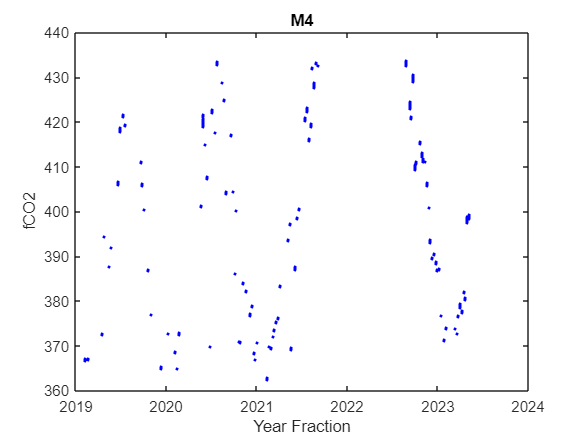



plot(m4.YearFraction, m4.fCO2sw, "b.")
title("M4")
ylabel("fCO2")
xlabel("Year Fraction")

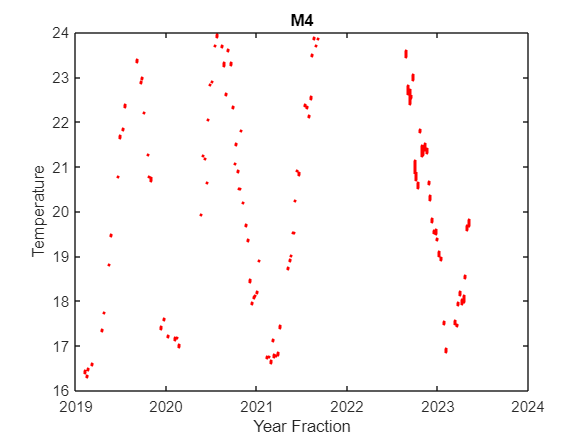


plot(m4.YearFraction, m4.IntakeTemp, ".r")
title("M4")
ylabel("Temperature")
xlabel("Year Fraction")

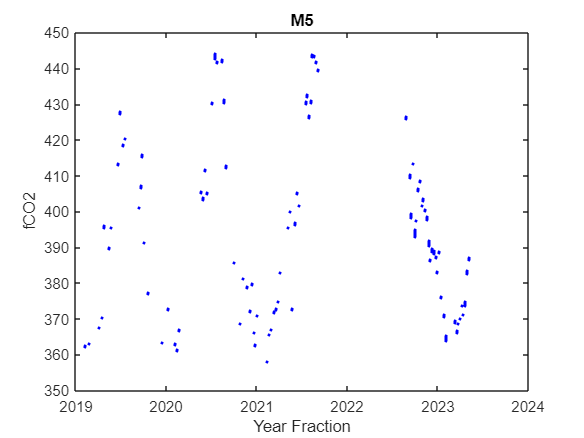



plot(m5.YearFraction, m5.fCO2sw, "b.")
title("M5")
ylabel("fCO2")
xlabel("Year Fraction")

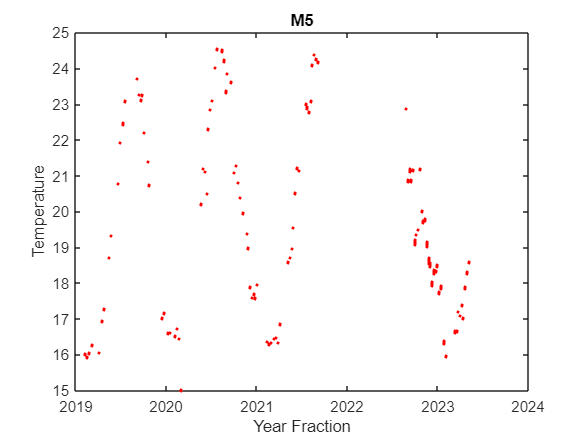


plot(m5.YearFraction, m5.IntakeTemp, ".r")
title("M5")
ylabel("Temperature")
xlabel("Year Fraction")

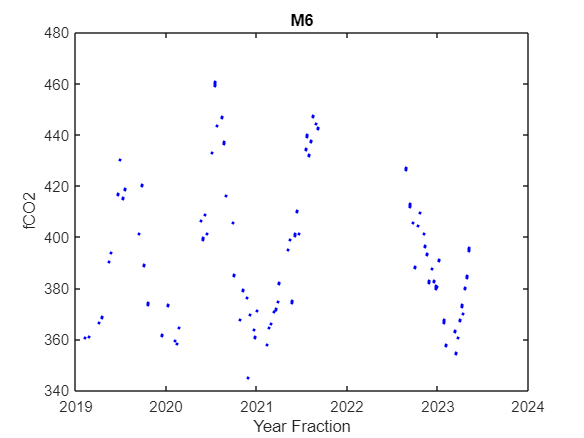



plot(m6.YearFraction, m6.fCO2sw, "b.")
title("M6")
ylabel("fCO2")
xlabel("Year Fraction")

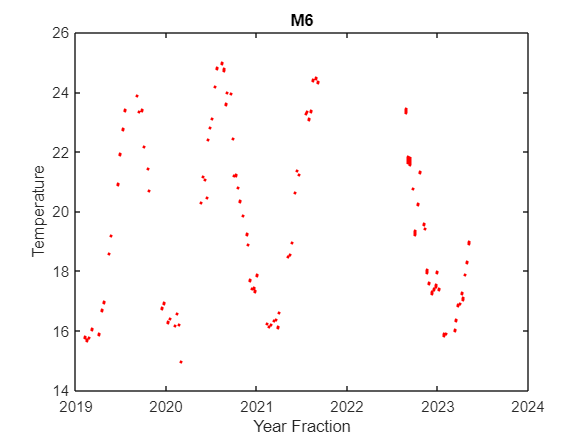


plot(m6.YearFraction, m6.IntakeTemp, ".r")
title("M6")
ylabel("Temperature")
xlabel("Year Fraction")

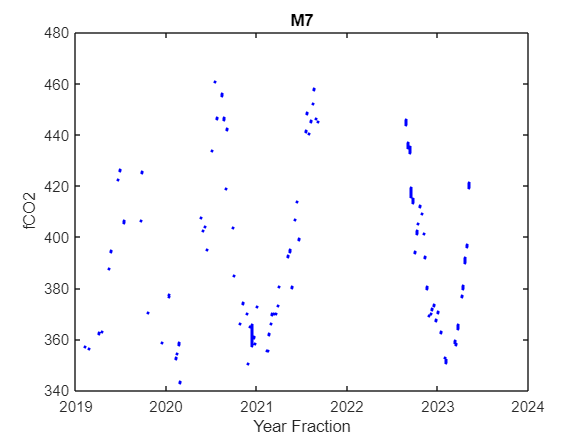



plot(m7.YearFraction, m7.fCO2sw, "b.")
title("M7")
ylabel("fCO2")
xlabel("Year Fraction")

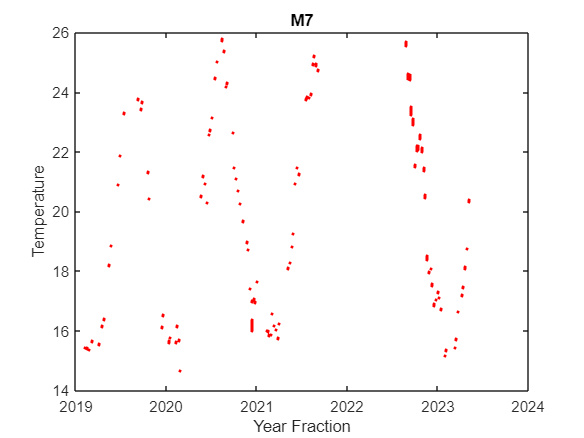


plot(m7.YearFraction, m7.IntakeTemp, ".r")
title("M7")
ylabel("Temperature")
xlabel("Year Fraction")

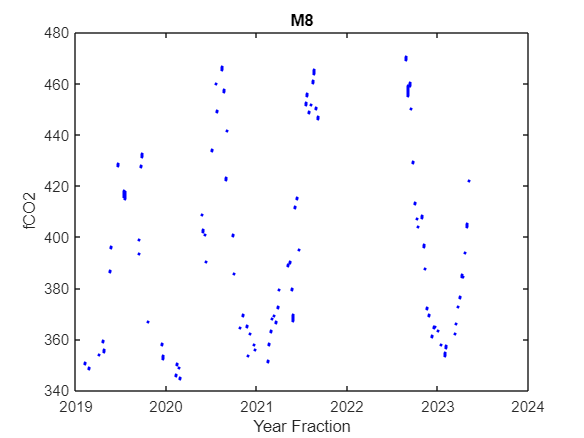



plot(m8.YearFraction, m8.fCO2sw, "b.")
title("M8")
ylabel("fCO2")
xlabel("Year Fraction")

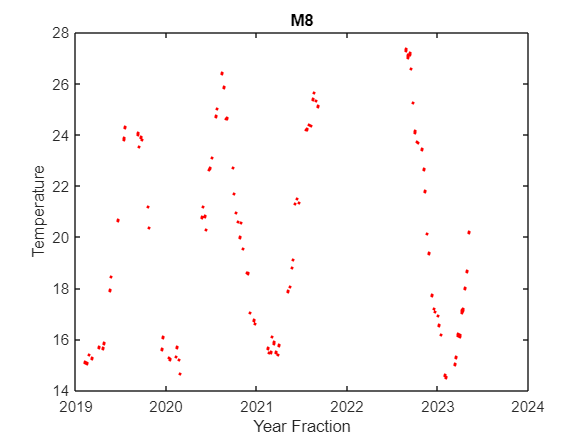


plot(m8.YearFraction, m8.IntakeTemp, ".r")
title("M8")
ylabel("Temperature")
xlabel("Year Fraction")

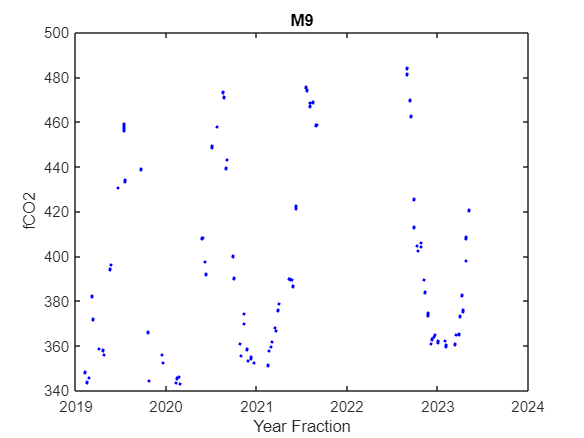



plot(m9.YearFraction, m9.fCO2sw, "b.")
title("M9")
ylabel("fCO2")
xlabel("Year Fraction")

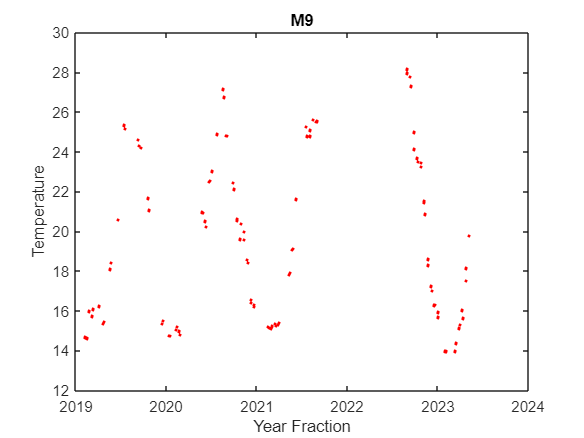


plot(m9.YearFraction, m9.IntakeTemp, ".r")
title("M9")
ylabel("Temperature")
xlabel("Year Fraction")

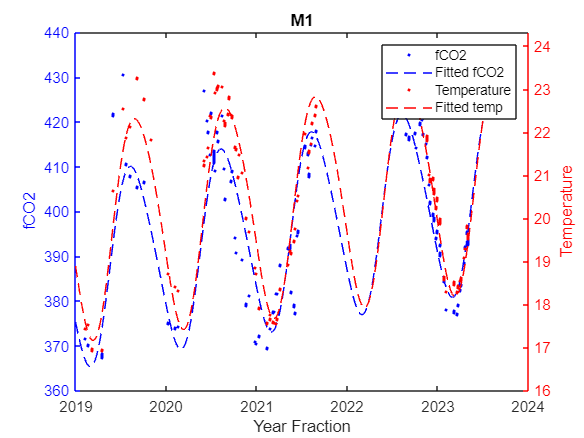

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m1.YearFraction, m1.fCO2sw, "b.")
title("M1")
hold on
plot(fitM1, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m1.YearFraction, m1.IntakeTemp, ".r")
hold on
plot(fitM1t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

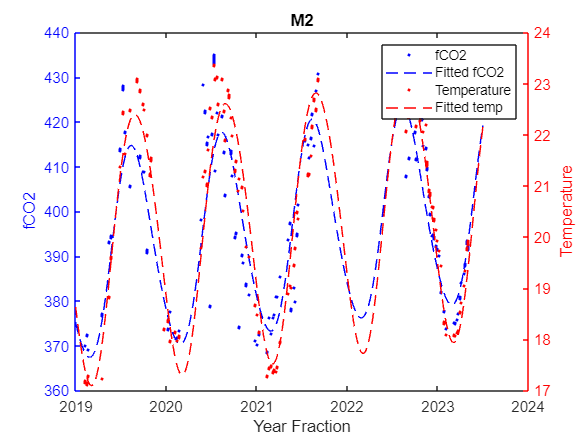

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m2.YearFraction, m2.fCO2sw, "b.")
hold on
plot(fitM2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m2.YearFraction, m2.IntakeTemp, ".r")
title("M2")
hold on
plot(fitM2t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

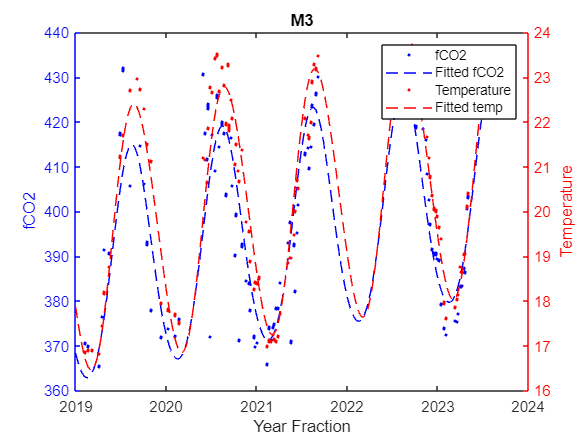

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m3.YearFraction, m3.fCO2sw, "b.")
hold on
plot(fitM3, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m3.YearFraction, m3.IntakeTemp, ".r")
title("M3")
hold on
plot(fitM3t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

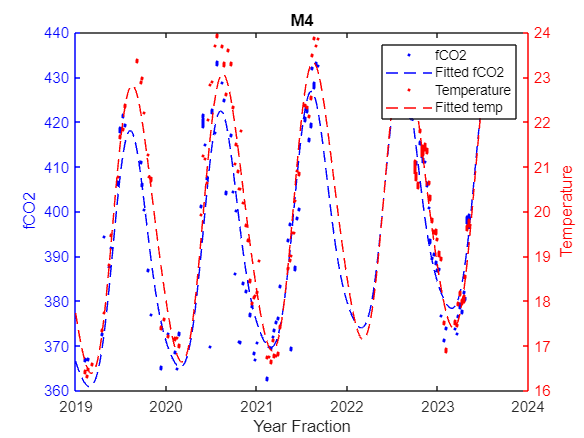

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m4.YearFraction, m4.fCO2sw, "b.")
hold on
plot(fitM4, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m4.YearFraction, m4.IntakeTemp, ".r")
title("M4")
hold on
plot(fitM4t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

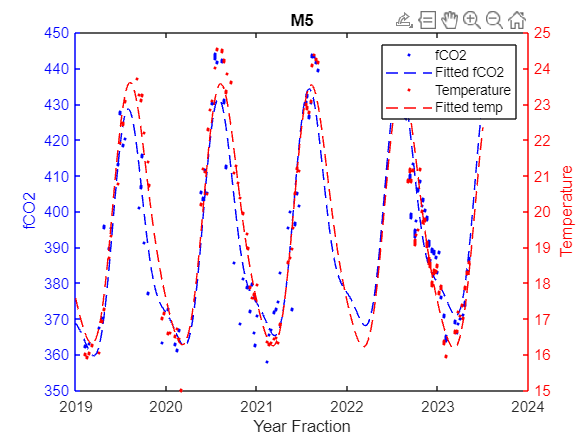

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m5.YearFraction, m5.fCO2sw, "b.")
hold on
plot(fitM5, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m5.YearFraction, m5.IntakeTemp, ".r")
title("M5")
hold on
plot(fitM5t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

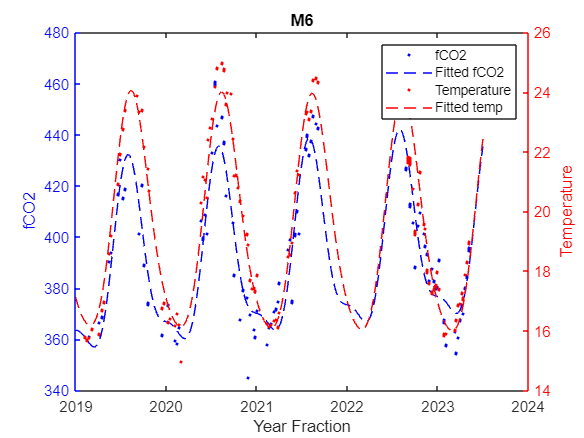

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m6.YearFraction, m6.fCO2sw, "b.")
hold on
plot(fitM6, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m6.YearFraction, m6.IntakeTemp, ".r")
title("M6")
hold on
plot(fitM6t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

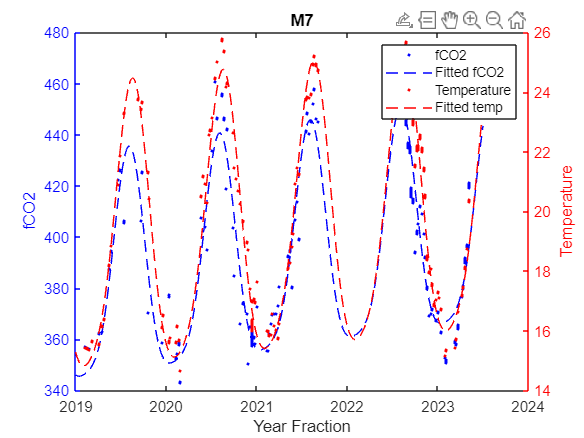

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m7.YearFraction, m7.fCO2sw, "b.")
hold on
plot(fitM7, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m7.YearFraction, m7.IntakeTemp, ".r")
title("M7")
hold on
plot(fitM7t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

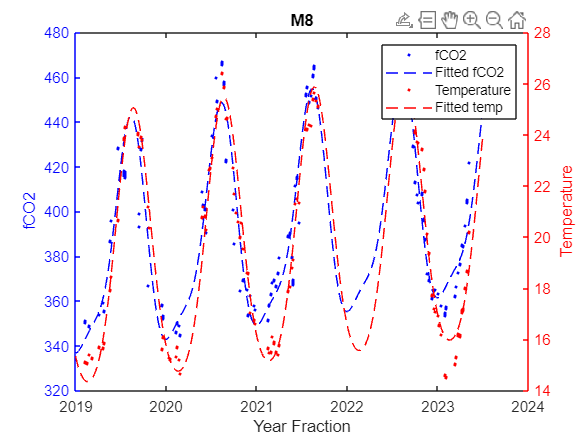

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m8.YearFraction, m8.fCO2sw, "b.")
hold on
plot(fitM8, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m8.YearFraction, m8.IntakeTemp, ".r")
title("M8")
hold on
plot(fitM8t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

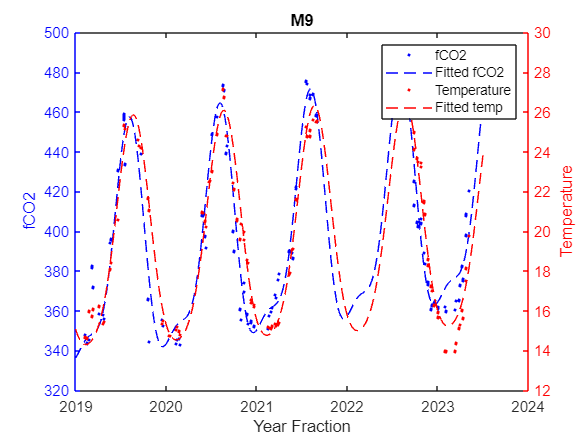

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m9.YearFraction, m9.fCO2sw, "b.")
hold on
plot(fitM9, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m9.YearFraction, m9.IntakeTemp, ".r")
title("M9")
hold on
plot(fitM9t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")